# Object Detection Using YOLO v2 Deep Learning

This example shows how to train a you only look once (YOLO) v2 object detector.

Deep learning is a powerful machine learning technique that you can use to train robust object detectors. Several techniques for object detection exist, including Faster R-CNN and you only look once (YOLO) v2. This example trains a YOLO v2 bottle detector using the `trainYOLOv2ObjectDetector` function. For more information, see [object detection using deep learning](docid:vision_doccenter#bvd8yot-1).

## **Clear Arguments**

clearvars;
clc;

## Set Arguments 

Download a pretrained detector to avoid having to wait for training to complete. If you want to train the detector, set the `doTraining` variable to true.

doTraining = true; % set true to train new network
visualizeAnchorBoxes = false; % set true to see plot of anchorbox # vs meanIoU
testDataset = true;  % set true to test new network on dataset

## Load Dataset

This example uses a small bottle dataset that contains 295 images. Each image contains one or two labeled instances of a bottle. A small dataset is useful for exploring the YOLO v2 training procedure, but in practice, more labeled images are needed to train a robust detector. Unzip the bottle images and load the bottle ground truth data.

%unzip bottleDatasetImages.zip
load(which('coco_dataset.mat'));

% make val2017 dataset and correct for filepaths
valDataset = images_val;
val_files = dir('../val2017'); %finds directory with file names
val_folder_path = val_files(1).folder;
fullImageName = fullfile(val_folder_path,valDataset(:,1));
valDataset(:,1) = fullImageName;

% repeat for train2017
trainDataset = images_train;
train_files = dir('../train2017'); %finds directory with file names
train_folder_path = train_files(1).folder;
fullImageName = fullfile(train_folder_path,trainDataset(:,1));
trainDataset(:,1) = fullImageName;

load(which('val_2014_dataset.mat'));
valDataset2014 = images_val_2014;
val_files = dir('../val2014'); %finds directory with file names
val_folder_path = val_files(1).folder;
fullImageName = fullfile(val_folder_path,valDataset2014(:,1));
valDataset2014(:,1) = fullImageName;

load(which('train_2014_dataset.mat'));
trainDataset2014 = images_train_2014;
train_files = dir('../train2014'); %finds directory with file names
train_folder_path = train_files(1).folder;
fullImageName = fullfile(train_folder_path,trainDataset2014(:,1));
trainDataset2014(:,1) = fullImageName;

bottleDataset = [valDataset;trainDataset;valDataset2014;trainDataset2014];
bottleDataset = cell2table(bottleDataset,...
    'VariableNames',{'imageFilename' 'bottle'});


## Correct Any Greyscale Images In The Dataset

% greyScaleImages = 0;
% coloredImages = 0;
% officialHeight = length(images_train_2014)
% 
% filteredDataset = [];
% filteredIndex = 1;
% 
% for i = 1:officialHeight
%     filePathToImage = images_train_2014{i,1};
%     filePathToImage = strcat('../train2014/',filePathToImage);
%     imageToTest = imread(string(filePathToImage));
%     imageInfo = size(imageToTest);
%     
%     if length(imageInfo) < 3 || imageInfo(3) == 1 
%         %bottleDataset([i],:) = [];
%         greyScaleImages = greyScaleImages + 1;
%     else
%         filteredDataset{filteredIndex,1} =  images_train_2014{i,1};
%         filteredDataset(filteredIndex,2) =  images_train_2014(i,2);
%         coloredImages = coloredImages + 1;    
%         filteredIndex = filteredIndex + 1;
%     end
% end
% 
% images_train_2014 = filteredDataset;
% length(images_train_2014)



The bottle data is stored in a two-column table, where the first column contains the image file paths and the second column contains the bottle bounding boxes.

% Display first few rows of the data set.
bottleDataset(1:4,:)

ans = 4×2 table
                        imageFilename                           bottle   
    _____________________________________________________    ____________

    {'C:\Users\Visitor\Desktop\val2017\000000002685.jpg'}    {8×4 double}
    {'C:\Users\Visitor\Desktop\val2017\000000005193.jpg'}    {1×4 double}
    {'C:\Users\Visitor\Desktop\val2017\000000006471.jpg'}    {2×4 double}
    {'C:\Users\Visitor\Desktop\val2017\000000007574.jpg'}    {2×4 double}


Split the data set into a training set for training the detector, and a test set for evaluating the detector. Select 60% of the data for training. Use the rest for evaluation.

rng(0);
shuffledIndices = randperm(height(bottleDataset));
train_splitPercentage = 0.75;
train_idx = floor(train_splitPercentage * length(shuffledIndices) );
trainingDataTbl = bottleDataset(shuffledIndices(1:train_idx),:);

val_splitPercentage = .10; % splits 
val_idx = floor(val_splitPercentage * length(shuffledIndices));
val_start_index = train_idx+1; val_stop_index = val_start_index+val_idx;
valDataTbl = bottleDataset(shuffledIndices(val_start_index:val_stop_index),:);

testDataTbl = bottleDataset(shuffledIndices(val_stop_index+1:end),:);
% save('test_split_dataset.mat', "testDataTbl");

Use `imageDatastore` and `boxLabelDatastore` to create datastores for loading the image and label data during training and evaluation.

imdsTrain = imageDatastore(trainingDataTbl{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,'bottle'));

imdsVal = imageDatastore(valDataTbl{:,'imageFilename'});
bldsVal = boxLabelDatastore(valDataTbl(:,'bottle')); 

imdsTest = imageDatastore(testDataTbl{:,'imageFilename'});
bldsTest = boxLabelDatastore(testDataTbl(:,'bottle'));

Combine image and box label datastores.

trainingData = combine(imdsTrain,bldsTrain);
valData = combine(imdsVal, bldsVal);
testData = combine(imdsTest,bldsTest);
% save('test_split_dataset', "testData", '-mat');

Display one of the training images and box labels.

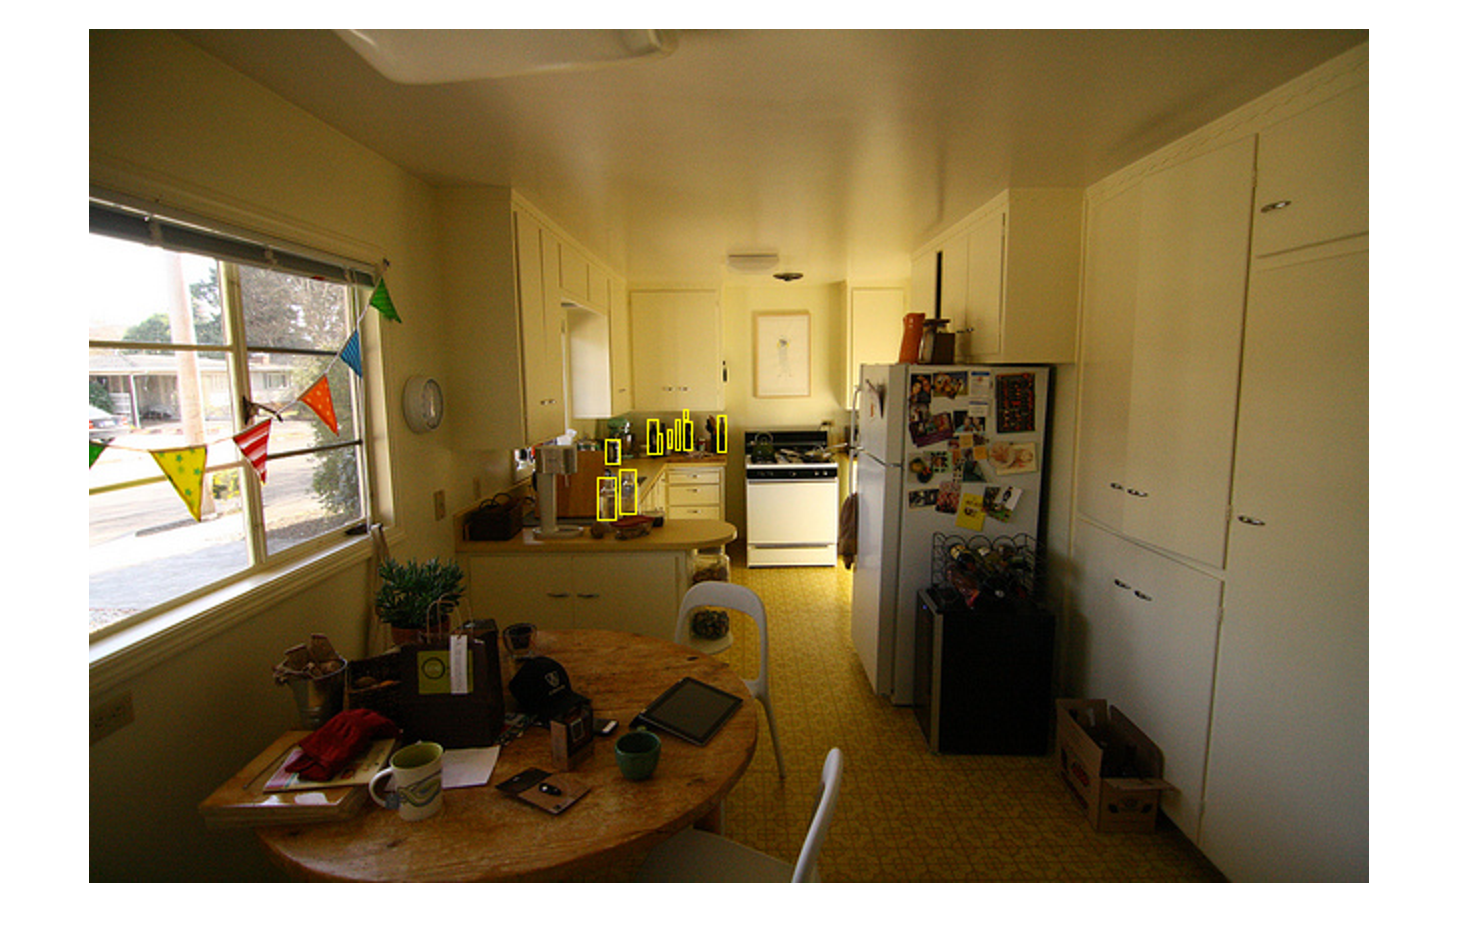

data = read(trainingData);
I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,'Rectangle',bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

## Create a YOLO v2 Object Detection Network

A YOLO v2 object detection network is composed of two subnetworks. A feature extraction network followed by a detection network. The feature extraction network is typically a pretrained CNN (for detials, see [Pretrained Deep Neural Networks](docid:nnet_ug#bvf9ych-1)). This example uses ResNet-50 for feature extraction. You can also use other pretrained networks such as MobileNet v2 or ResNet-18 can also be used depending on application requirements. The detection sub-network is a small CNN compared to the feature extraction network and is composed of a few convolutional layers and layers specific for YOLO v2.

Use the [`yolov2Layers`](docid:vision_ref#mw_b1e7b78e-2ce3-4d2f-ad8d-f5acd725f170) function to create a YOLO v2 object detection network automatically given a pretrained ResNet-50 feature extraction network. `yolov2Layers` requires you to specify several inputs that parameterize a YOLO v2 network:

- Network input size

- Anchor boxes

- Feature extraction network 

First, specify the network input size and the number of classes. When choosing the network input size, consider the minimum size required by the network itself, the size of the training images, and the computational cost incurred by processing data at the selected size. When feasible, choose a network input size that is close to the size of the training image and larger than the input size required for the network. To reduce the computational cost of running the example, specify a network input size of [224 224 3], which is the minimum size required to run the network.

inputSize = [224 224 3];

Define the number of object classes to detect.

numClasses = width(bottleDataset)-1;

Note that the training images used in this example are bigger than 224-by-224 and vary in size, so you must resize the images in a preprocessing step prior to training.

Next, use  [estimateAnchorBoxes](docid:vision_ref#mw_cba7b62d-6557-41e6-9e4d-73ec50667c6d) to estimate anchor boxes based on the size of objects in the training data. To account for the resizing of the images prior to training, resize the training data for estimating anchor boxes. Use `transform` to preprocess the training data, then define the number of anchor boxes and estimate the anchor boxes. Resize the training data to the input image size of the network using the supporting function `preprocessData`.

trainingDataForEstimation = transform(trainingData,@(data)preprocessData(data,inputSize))

trainingDataForEstimation =   TransformedDatastore with properties:

    UnderlyingDatastore: [1×1 matlab.io.datastore.CombinedDatastore]
             Transforms: {@(data)preprocessData(data,inputSize)}
            IncludeInfo: 0


## **Determine Best Number of Anchors**

Sweep over all possible anchors to determine best fit uncomment to see the graph of performance

    if visualizeAnchorBoxes
    maxNumAnchors = 30;
    meanIoU = zeros([maxNumAnchors,1]);
    anchorBoxes = cell(maxNumAnchors, 1);
    for k = 1:maxNumAnchors
        % Estimate anchors and mean IoU.
        [anchorBoxes{k},meanIoU(k)] = estimateAnchorBoxes(trainingDataForEstimation,k);    
    end
    
    figure
    plot(1:maxNumAnchors,meanIoU,'-o')
    ylabel("Mean IoU")
    xlabel("Number of Anchors")
    title("Number of Anchors vs. Mean IoU")
end


## Visually Inspect, Determine A Good NumAnchors

numAnchors = 23;

**Changed from trainingData in the example to trainingDataForEstimation to put it in the correct format.**

[anchorBoxes, meanIoU] = estimateAnchorBoxes(trainingDataForEstimation, numAnchors)

anchorBoxes =     16     4
    91   166
    62    34
    13     8
    92    28
    22    12
    37    37
    37     9
    24     7
    20    28


meanIoU = 0.7190

For more information on choosing anchor boxes, see [Estimate Anchor Boxes from Training Data](docid:vision_ug#mw_671cb7a6-5a7a-4147-acf3-3e1fd7d3dfd7) (Computer Vision Toolbox™) and [Anchor Box Basics](docid:vision_ug#mw_f9f22f48-0ad0-4f37-8bc1-22a2046637f2).

Now, use `resnet50` to load a pretrained ResNet-50 model.

featureExtractionNetwork = resnet101;
network_string = "resnet101_9"; % this is to append to table, must be str of network

Select `'activation_40_relu'` as the feature extraction layer to replace the layers after `'activation_40_relu'` with the detection subnetwork. This feature extraction layer outputs feature maps that are downsampled by a factor of 16. This amount of downsampling is a good trade-off between spatial resolution and the strength of the extracted features, as features extracted further down the network encode stronger image features at the cost of spatial resolution. Choosing the optimal feature extraction layer requires empirical analysis.

featureLayer = 'res4b5_relu'; % chosen googlenet layer

Create the YOLO v2 object detection network. 

lgraph = yolov2Layers(inputSize,numClasses,anchorBoxes,featureExtractionNetwork,featureLayer);

You can visualize the network using `analyzeNetwork` or Deep Network Designer from Deep Learning Toolbox™.

If more control is required over the YOLO v2 network architecture, use Deep Network Designer to design the YOLO v2 detection network manually. For more information, see [Design a YOLO v2 Object Detection Network](docid:vision_ug#mw_bcbd5375-ed75-4616-b57b-469e29139033).

## Data Augmentation

Data augmentation is used to improve network accuracy by randomly transforming the original data during training. By using data augmentation you can add more variety to the training data without actually having to increase the number of labeled training samples.

Use `transform` to augment the training data by randomly flipping the image and associated box labels horizontally. Note that data augmentation is not applied to the test data. Ideally, test data should be representative of the original data and is left unmodified for unbiased evaluation.

augmentedTrainingData = transform(trainingDataForEstimation,@augmentData);

Read the same image multiple times and display the augmented training data.

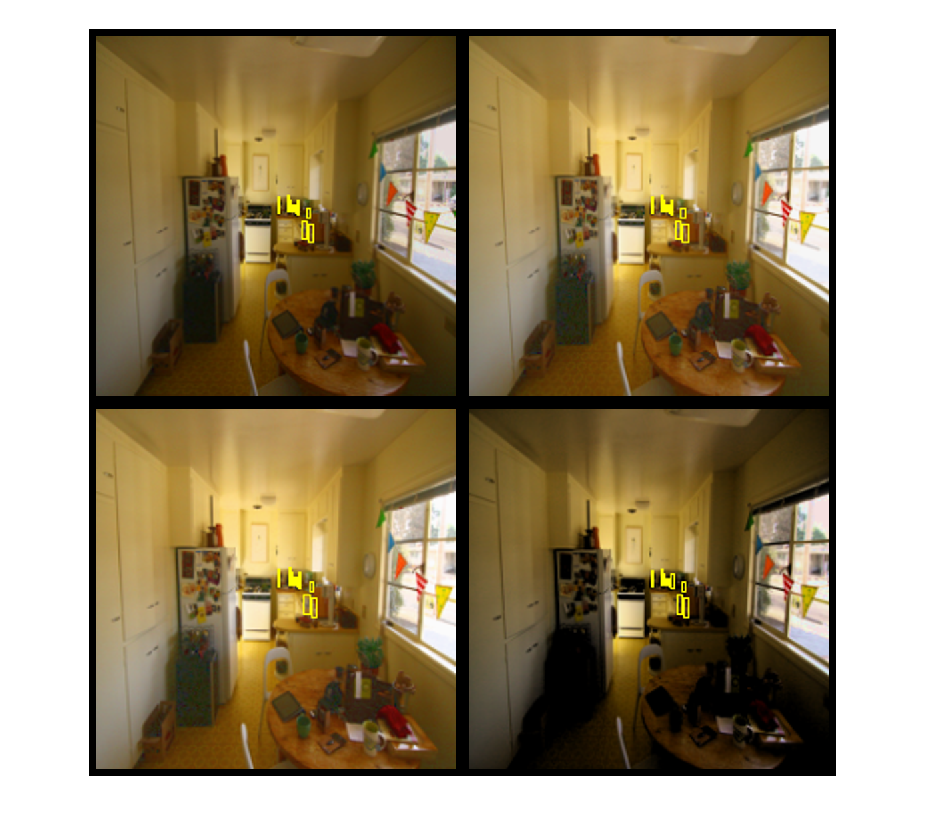

% Visualize the augmented images.
augmentedData = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    data{2} = correctData(data{2});
    augmentedData{k} = insertShape(data{1},'Rectangle',data{2});
    reset(augmentedTrainingData);
end
figure
montage(augmentedData,'BorderSize',10)

## Preprocess Training Data

Preprocess the augmented training data to prepare for training.

preprocessedTrainingData = transform(augmentedTrainingData,@(data)preprocessData(data,inputSize));

Read the preprocessed training data.

data = read(preprocessedTrainingData);

Display the image and bounding boxes.

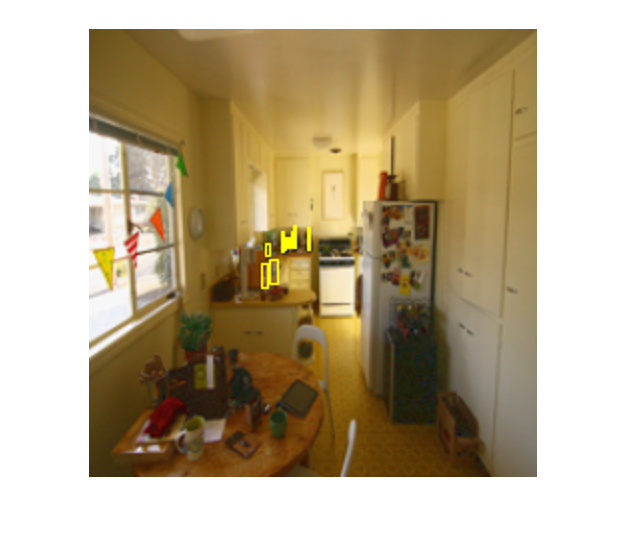

I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,'Rectangle',bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

preprocessedValData = transform(valData,@(data)preprocessData(data,inputSize));

## Train YOLO v2 Object Detector

Use `trainingOptions` to specify network training options. Set `'CheckpointPath'` to a temporary location. This enables the saving of partially trained detectors during the training process. If training is interrupted, such as by a power outage or system failure, you can resume training from the saved checkpoint.

learningRate = 1e-3;
epochSize = 20;
solverMethod = 'sgdm';
featureLayerString = string(featureLayer);
miniBatchsize = 16;
% period = 10;
% drop_factor = .9;
options = trainingOptions(solverMethod, ...
        'MiniBatchSize', miniBatchsize, ....
        'InitialLearnRate',learningRate, ...
        'MaxEpochs',epochSize,...
        'CheckpointPath', tempdir, ...
        'Shuffle','never');
%         'LearnRateSchedule', 'piecewise', ...
%         'LearnRateDropPeriod', period, ...
%         "LearnRateDropFactor", drop_factor, ...

Use [`trainYOLOv2ObjectDetector`](docid:vision_ref#mw_0ff9d26a-9a79-4333-a1b1-ba03c8539ee3) function to train YOLO v2 object detector if `doTraining` is true. Otherwise, load the pretrained network.

  if doTraining       
    % Train the YOLO v2 detector.
    [detector,info] = trainYOLOv2ObjectDetector(preprocessedTrainingData,lgraph,options);
else
    % Load another object detector and evaluate that performance
    ObjectDetector = load('YOLOv2_MBSize_10_MaxEpoch_20_InitLearnRate_1e-3_NumAnchors_15_Acc_11.mat');
    detector = ObjectDetector.detector;
end

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* bottle

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |        12.14 |        147.4 |          0.0010 |
|       1 |          50 |       00:00:56 |         1.44 |          2.1 |          0.0010 |
|       1 |         100 |       00:01:52 |         1.71 |          2.9 |          0.0010 |
|       1 |         150 |       00:02:51 |         1.90 |          3.6 |          0.0010 |
|       1 |         200 |       00:03:47 |         2.08

This example was verified on an NVIDA™ Titan X GPU with 12 GB of memory. If your GPU has less memory, you may run out of memory. If this happens, lower the `'MiniBatchSize'` using the `trainingOptions` function. Training this network took approximately 7 minutes using this setup. Training time varies depending on the hardware you use.

As a quick test, run the detector on one test image. Make sure you resize the image to the same size as the training images.

**TEST DETECTOR **

Tests the detector on an image from the test dataset reserved earlier

if testDataset
    % test detector on    all the testing data to see if there is any detection
    detectedImages = 0;
    missedImages = 0;
    imageIndices = 1;
    for i = 1:length(valDataTbl.imageFilename) 
        
        % preprocess the data for detection
        I = imread(valDataTbl.imageFilename{i});
        I = imresize(I,inputSize(1:2));
        [bboxes,scores] = detect(detector,I);
        
        if(~isempty(bboxes))
            I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
          
            detectedImagesIndexArray(imageIndices) = i;
            imageIndices = imageIndices + 1;
            
            detectedImages =  detectedImages + 1;
        else
            missedImages = missedImages + 1;
        end
    end
    detector_accuracy = detectedImages/height(valDataTbl) * 100;
    fprintf('total images: %d\n',length(valDataTbl.imageFilename));
    fprintf('detected images: %d\n',detectedImages);
    fprintf('missed images: %d\n',missedImages);
    fprintf('Accuracy Percentage, detected/missed: %f\n',detectedImages/length(valDataTbl.imageFilename) * 100);

total images: 1775


detected images: 1065


missed images: 710


Accuracy Percentage, detected/missed: 60.000000


## Display A Detected Image From The Detected Images Set

Usage: replace* detectedImagesIndexArray(3) *with *detectedImagesIndexArray( your desired number in the range of detectedImagesIndex range )*

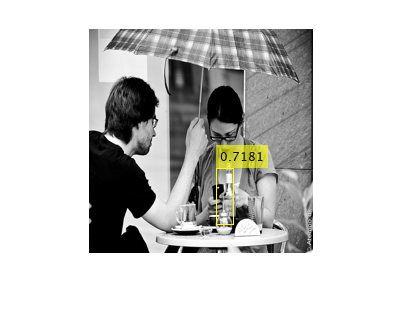

    if detectedImages > 0 
        figure
        img = imread(valDataTbl.imageFilename{detectedImagesIndexArray(2)});
        img = imresize(img,inputSize(1:2));
        [bboxes,scores] = detect(detector,img);
        if(~isempty(bboxes))
            img = insertObjectAnnotation(img,'rectangle',bboxes,scores); 
        end
        imshow(img)
    end


end

## Evaluate Detector Using Test Set

Evaluate the trained object detector on a large set of images to measure the performance. Computer Vision Toolbox™ provides object detector evaluation functions to measure common metrics such as average precision (`evaluateDetectionPrecision`) and log-average miss rates (`evaluateDetectionMissRate`). For this example, use the average precision metric to evaluate performance. The average precision provides a single number that incorporates the ability of the detector to make correct classifications (precision) and the ability of the detector to find all relevant objects (recall).

Apply the same preprocessing transform to the test data as for the training data. Note that data augmentation is not applied to the test data. Test data should be representative of the original data and be left unmodified for unbiased evaluation.

% preprocessed test data was here but moved to line 119

Run the detector on all the test images.

detectionResults = detect(detector, preprocessedValData);

Evaluate the object detector using average precision metric.

[ap,recall,precision] = evaluateDetectionPrecision(detectionResults, preprocessedValData);
save(network_string, 'detector', 'ap', 'recall', 'precision'); % save detector
% Append values to existing table
% load('detector_table_info.mat');
% detector_number = height(detector_table); % get amount of current detectors
% detector_number = detector_number + 1;
% network_string = sprintf("%s_%d", network_string, detector_number);
% save(network_string, 'detector', 'ap', 'recall', 'precision'); % save detector
% solverMethod = string(solverMethod);
% add_on = {network_string,solverMethod,height(trainingDataTbl),splitPercentage,inputSize(1:2),featureLayerString,miniBatchsize,learningRate,numAnchors,detector_accuracy,ap,NaN,NaN};
% add_Table = cell2table(add_on,'VariableNames', variable_names);
% detector_table = [detector_table;add_Table] %append to the end
% save('detector_table_info.mat', 'detector_table', 'variable_names'); %save 
% save(network_string, 'detector'); % save detector

The precision/recall (PR) curve highlights how precise a detector is at varying levels of recall. The ideal precision is 1 at all recall levels. The use of more data can help improve the average precision but might require more training time. Plot the PR curve.

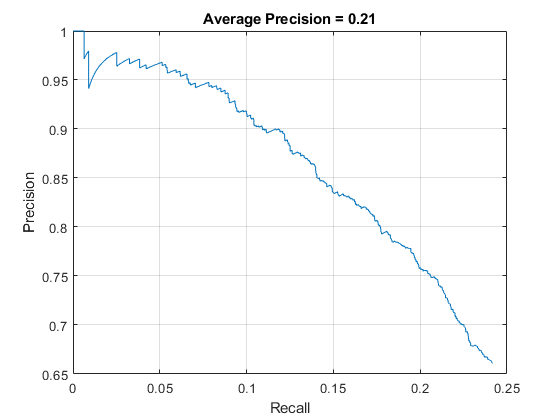

figure
plot(recall,precision)
xlabel('Recall')
ylabel('Precision')
grid on
title(sprintf('Average Precision = %.2f',ap))

## Code Generation

Once the detector is trained and evaluated, you can generate code for the `yolov2ObjectDetector` using GPU Coder™. See [Code Generation For Object Detection Using YOLO v2](docid:gpucoder_examples#mw_f24928a4-a92d-4db7-ba44-8e8feb2780f6) example for more details.

## Supporting Functions

function B = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.
B = cell(size(A));

I = A{1};
sz = size(I);
if numel(sz)==3 && sz(3) == 3
    I = jitterColorHSV(I,...
        'Contrast',0.2,...
        'Hue',0,...
        'Saturation',0.1,...
        'Brightness',0.2);
end

% Randomly flip and scale image.
tform = randomAffine2d('XReflection',true,'Scale',[1 1.1]);
% tform = randomAffine2d('XReflection',true,'Scale',[1 1.1], "YReflection", true, 'Rotation', [0 360]);
rout = affineOutputView(sz,tform,'BoundsStyle','CenterOutput');
B{1} = imwarp(I,tform,'OutputView',rout);

% Apply same transform to boxes.
[B{2},indices] = bboxwarp(A{2},tform,rout,'OverlapThreshold',0.25);
B{3} = A{3}(indices);

% Return original data only when all boxes are removed by warping.
if isempty(indices)
    B = A;
end
end

function data = preprocessData(data,targetSize)
% Resize image and bounding boxes to the targetSize.
scale = targetSize(1:2)./size(data{1},[1 2]);
data{1} = imresize(data{1},targetSize(1:2));
data{2} = floor(data{2});
%data{2}(2) = 1;
data{2} = correctData(data{2});
data{2} = bboxresize(data{2},scale); 
end

function data = correctData(data)

D = size(data);
length = D(1) * D(2);
if min(data,[],'all') == 0 
   for i=1:length
       if data(i) == 0 
           data(i) = 1;
       end
   end
end

end

## References

[1] Redmon, Joseph, and Ali Farhadi. "YOLO9000: Better, Faster, Stronger." 2017 IEEE Conference on Computer Vision and Pattern Recognition (CVPR). IEEE, 2017.

*Copyright 2019 The MathWorks, Inc.*